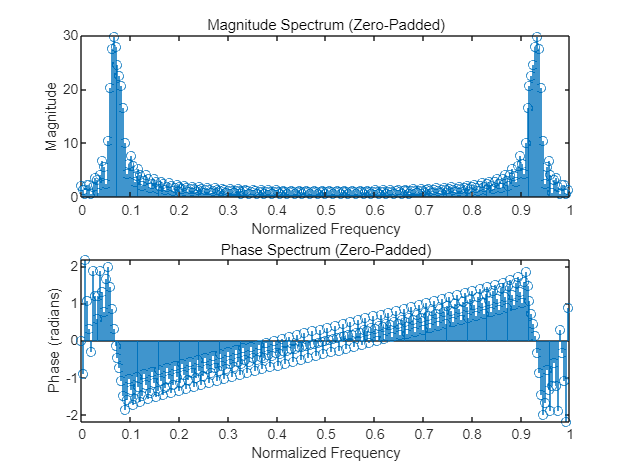

% LAB 2.2.5.2 刘兴琰 AI1 202264690069
N = 64;
N_padded = 256;
k = 0:N-1;
x_k = cos(2 * pi * k / 15) + 0.75 * cos(2.3 * pi * k / 15);
x_k_padded = [x_k zeros(1, N_padded - N)];
X_k_padded = fft(x_k_padded, N_padded);
freq_padded = (0:N_padded-1)/N_padded;

subplot(2,1,1);
stem(freq_padded, abs(X_k_padded));
title('Magnitude Spectrum (Zero-Padded)');
xlabel('Normalized Frequency');
ylabel('Magnitude');

subplot(2,1,2);
stem(freq_padded, angle(X_k_padded));
title('Phase Spectrum (Zero-Padded)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');